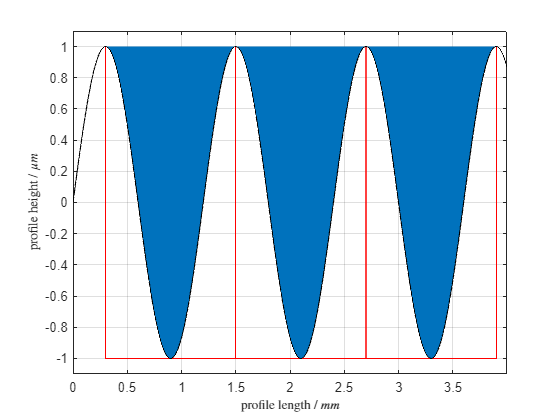

clc;clear;close all;
format long
dx = 0.5;
load("..\..\data\profiles for case studies\simple_sin_1_open_peak.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z, dx, M);


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean");
HDhm_theo = 2;
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean");
HDwm_theo = 1200;
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean");
syms x
f(x)=sin(2*pi*x/1200);
HDvm_theo = double(int(f(x)+1, 300, 1500)/(length(z)*dx));
HDlm = feature_parameter(z, dx, M, "All", 1, "HDl", "Mean");
l = int(sqrt(1+diff(f(x),x)^2),[300 1500]);
HDlm_theo = double(l);
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean");
k(x) = diff(diff(f(x),x),x)/(1 + diff(f(x),x)^2)^(3/2);
Rmvc_theo = double(k(900));
% output table
T(1) = struct('parameter',"Mean motif height",'Feature_Characterization',HDhm,'theoretical_value',HDhm_theo,'deviation',abs(HDhm-HDhm_theo)*100/HDhm_theo);
T(2) = struct('parameter',"Mean motif width",'Feature_Characterization',HDwm,'theoretical_value',HDwm_theo,'deviation',abs(HDwm-HDwm_theo)*100/HDwm_theo);
T(3) = struct('parameter',"Mean motif volume",'Feature_Characterization',HDvm,'theoretical_value',HDvm_theo,'deviation',abs(HDvm-HDvm_theo)*100/HDvm_theo);
T(4) = struct('parameter',"Mean motif dev. length",'Feature_Characterization',HDlm,'theoretical_value',HDlm_theo,'deviation',abs(HDlm-HDlm_theo)*100/HDlm_theo);
T(5) = struct('parameter',"Mean motif pit curvature",'Feature_Characterization',Rmvc,'theoretical_value',Rmvc_theo,'deviation',abs(Rmvc-Rmvc_theo)*100/Rmvc_theo);
T

T = 1×5 struct array with fields:
    parameter
    Feature_Characterization
    theoretical_value
    deviation



load("..\..\data\profiles for case studies\sinus_04_zeros_04.mat")
M = watershed_segmentation(z,dx,"H","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean");
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean");
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean");
syms x
f(x)=sin(2*pi*x/800);
HDvm_theo = abs(double(int(f(x), 400, 800)/((length(z)-1)*dx)));
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean");
Rmpc = feature_characterization(z, dx, "P", "Wolfprune 0.1", "All", "Curvature", "Mean");

% Pits are plateaus with 2 points with same height!
syms x
f(x)=sin(2*pi*x/800);
k(x)=diff(diff(f(x),x),x)/(1 + diff(f(x),x)^2)^(3/2);
Rmvc_theo = double(k(600));

T(1) = struct('parameter',"Mean motif height",'Feature_Characterization',HDhm,'theoretical_value',max(z) -min(z));
T(2) = struct('parameter',"Mean motif width",'Feature_Characterization',HDwm,'theoretical_value',HDwm_theo);
T(3) = struct('parameter',"Mean motif volume",'Feature_Characterization',HDvm,'theoretical_value',HDvm_theo);
T(4) = struct('parameter',"Mean motif dev. length",'Feature_Characterization',HDlm,'theoretical_value',HDlm_theo);
T(5) = struct('parameter',"Mean motif pit curvature",'Feature_Characterization',Rmvc,'theoretical_value',Rmvc_theo);
T(6) = struct('parameter',"Mean motif peak curvature",'Feature_Characterization',Rmpc,'theoretical_value',0);
T

load("..\..\data\profiles for case studies\kuppen_taeler_4mm.mat")
figure
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvx = feature_parameter(z, dx, M, "All", 1, "HDv", "Max")
syms x
f(x)=-sin(2*pi*x/800);
HDvm_theo = double(int(f(x), 0, 400))
HDvmin = feature_parameter(z, dx, M, "All", 1, "HDv", "Min")
HDvm_theo = 2*double(int(f(x)+1, 0, 200))
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles for case studies\Luftpresser_1_56_ak.mat")
M = watershed_segmentation(z, dx, "D","Wolfprune", 0.5);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles for case studies\zeros_kuppen_taeler.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles for case studies\tstRSm_random.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles for case studies\sinus_04_sinus_04.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles for case studies\Bu_1_56_ak.mat")
M = watershed_segmentation(z,dx,"D","Width","opt");
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
RSm = 182; % 
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
